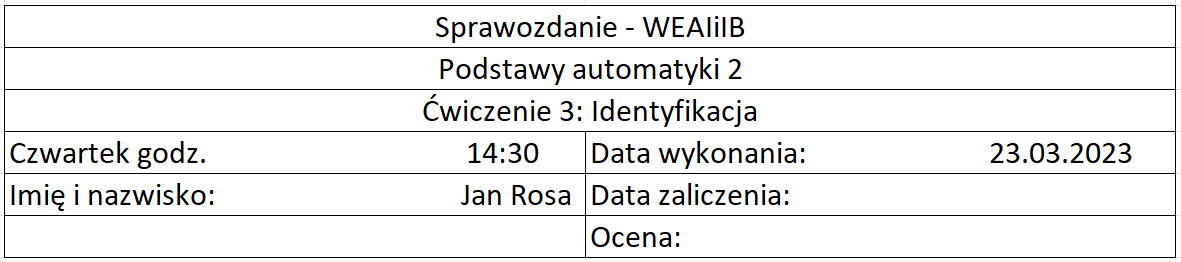

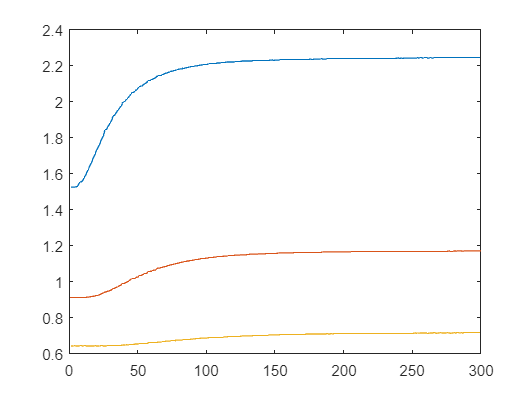

load pomiary_3out.mat
plot(pomiary_3out)

obiektA21 =
 
               0.7179
  exp(-7*s) * --------
              30 s + 1
 
Continuous-time transfer function.



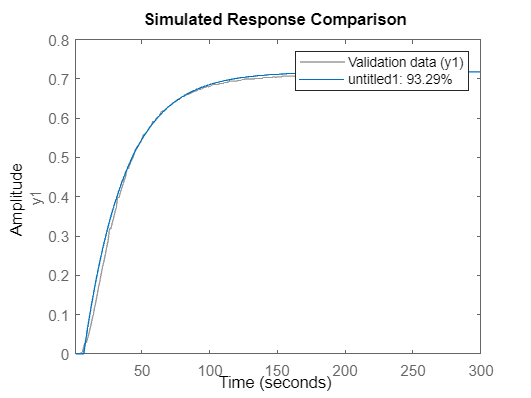

y1=pomiary_3out(:,1) - pomiary_3out(1,1);
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
y3=pomiary_3out(:,3) - pomiary_3out(1,3);
t = 1:300;
k1=(y1(300,1)-y1(1,1))/1.0; T1 = 30; theta1 = 7;
k2=(y2(300,1)-y2(1,1))/1.0; T2 = 45; theta2 = 17;
k3=(y3(300,1)-y3(1,1))/1.0; T3 = 65; theta3 = 38;
id1rz(k1, T1, theta1, y1, t)

obiektA21 =
 
                0.2586
  exp(-17*s) * --------
               45 s + 1
 
Continuous-time transfer function.



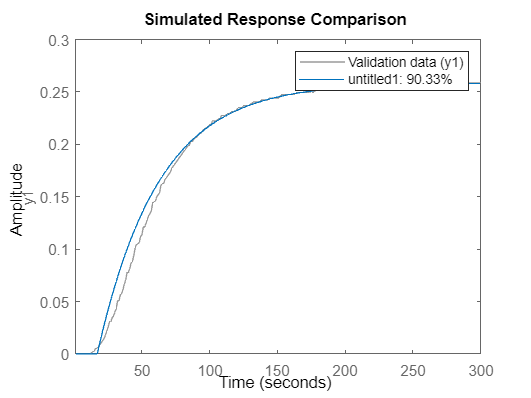

id1rz(k2, T2, theta2, y2, t)

obiektA21 =
 
               0.07414
  exp(-38*s) * --------
               65 s + 1
 
Continuous-time transfer function.



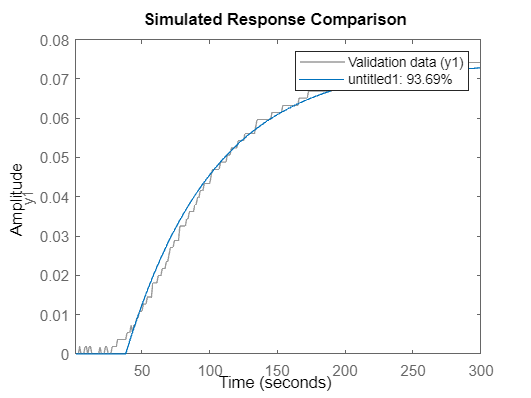

id1rz(k3, T3, theta3, y3, t)

K0 = 1; T1 = 5; T2 = 5; theta = 3;
[par, blad] = fminsearch('identB1',[K0,T1,T2,theta])

par =     0.7132    4.7081   27.3659   -5.6119


blad = 1.5409e-05


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                         0.7132
  exp(-5.61*s) * -----------------------
                 128.8 s^2 + 32.07 s + 1
 
Continuous-time transfer function.



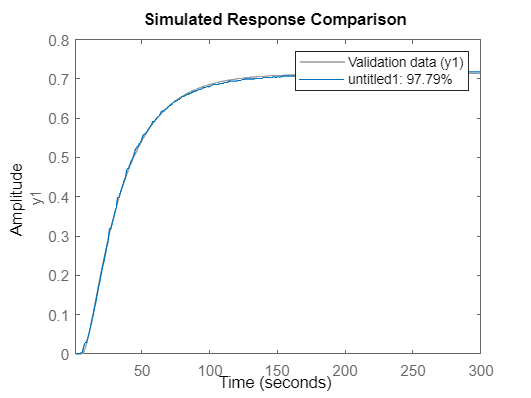

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y1, ones(size(y)), 1))

K0 = k2; T1 = 5; T2 = 5; theta = 10;
[par, blad] = fminsearch('identB2',[K0,T1,T2,theta])

par =     0.2573   39.2450   10.4565   14.8580


blad = 2.0075e-06


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                         0.2573
  exp(-14.9*s) * ----------------------
                 410.4 s^2 + 49.7 s + 1
 
Continuous-time transfer function.



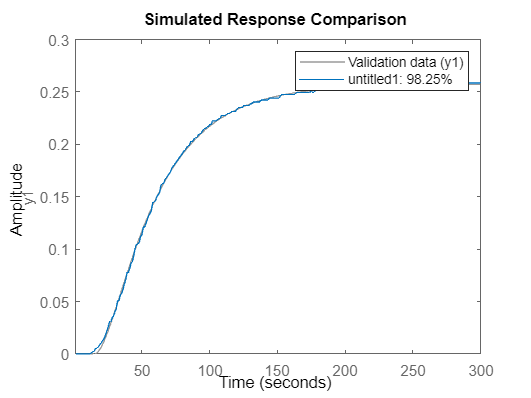

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y2, ones(size(y)), 1))

K0 = k2; T1 = 5; T2 = 5; theta = 10;
[par, blad] = fminsearch('identB2',[K0,T1,T2,theta])

obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))
y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y2, ones(size(y)), 1))

K0 = k2; T1 = 5; T2 = 5; theta = 10;
[par, blad] = fminsearch('identB3',[K0,T1,T2,theta])

par =     0.0735   24.8261   51.0234  -24.8344


blad = 7.7383e-07


obiektA24 = tf([0 0 par(1)], [par(3)*par(2) par(2)+par(3) 1], 'Inputdelay', abs(par(4)))

obiektA24 =
 
                        0.07347
  exp(-24.8*s) * ----------------------
                 1267 s^2 + 75.85 s + 1
 
Continuous-time transfer function.



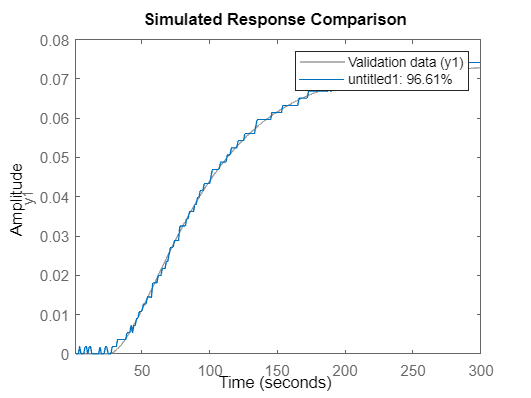

y = step(obiektA24, t);
figure
title("Obiekt C, metoda 2.4")
compare(iddata(y, ones(size(y)), 1), iddata(y3, ones(size(y)), 1))

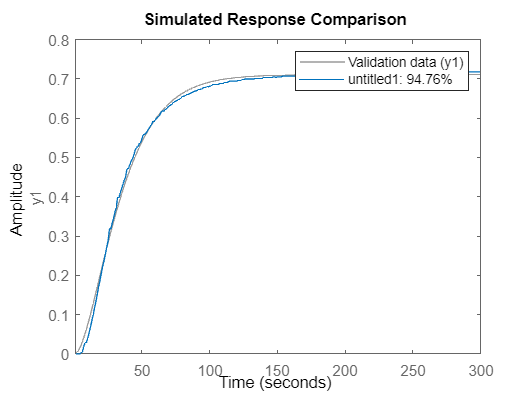

N = 2:6;
K0 = 2;
T0 = 10;
global n;
for i = N
    n=i;
    [par, blad] = fminsearch('identC1',[K0,T0]);
    s = tf('s');
    obiekt =  par(1) * (1/(par(2)*s + 1))^i;
    y_sym = step(obiekt, t);
    figure
    blod = num2str(blad);
    if i == 2
    compare(iddata(y_sym, ones(size(y)), 1), iddata(y1, ones(size(y)), 1))
    end
end

function [] = id1rz(k, T, theta, y, t)
obiektA21 = tf([0 k], [T 1], 'Inputdelay', theta)
[yA1, tA1] = step(obiektA21, t);
figure
hold on; grid on;
plot(tA1, yA1, t, y)
hold off;
compare(iddata(y, ones(size(y)), 1), iddata(yA1, ones(size(y)), 1))
end